# Face Recognition System on Cropped Yale database (with and without  the 3 PC)

### Data preparation

% Constants
rnum = 192;
cnum = 168;
k = 1000;
Train_data_count = 40;
Leave_top_k = 3;

main_folder = "\Yale";
folders_list = dir(main_folder);

% Getting a list of all folders in the main folder (ignoring . and .. entries)
folders_list = folders_list([folders_list.isdir]);
folders_list = folders_list(~ismember({folders_list.name}, {'.', '..'}));

% Initialize counters for training and test images
train_img_count = 0;
test_img_count = 0;

% Loop through folders and count number of training and test images
for i = 1:numel(folders_list)
    current_folder = main_folder + "\" + folders_list(i).name;
    images_list = dir(fullfile(current_folder, '*.pgm')); % Get list of images
    images_count = numel(images_list);
    train_img_count = train_img_count + Train_data_count;
    test_img_count = test_img_count + (images_count - Train_data_count);
end

% Preallocating variables
train_mean_vector = zeros(rnum*cnum, 1);
train_img = cell(1, train_img_count);
test_img = cell(1, test_img_count);
train_img_folder = zeros(1, train_img_count);
test_img_folder = zeros(1, test_img_count);
train_img_matrix = zeros(rnum*cnum, train_img_count);
test_img_matrix = zeros(rnum*cnum, test_img_count);
train_img_index = 0;
test_img_index = 0;

% Looping through the folders and images
for i = 1:numel(folders_list)
    current_folder = main_folder + "\" + folders_list(i).name;
    images_list = dir(fullfile(current_folder, '*.pgm')); % Get list of images
    images_count = numel(images_list);
    
    for j = 1:images_count
        new_file_path = fullfile(images_list(j).folder, images_list(j).name);
        
        if j <= Train_data_count % Training data
            train_img_index = train_img_index + 1;
            train_img{train_img_index} = new_file_path;
            train_img_folder(train_img_index) = i;
            new_image = imread(new_file_path);
            new_image = double(new_image);
            train_img_matrix(:, train_img_index) = new_image(:);
            train_mean_vector = train_mean_vector + new_image(:);
            
        else % Testing data
            test_img_index = test_img_index + 1;
            test_img{test_img_index} = new_file_path;
            test_img_folder(test_img_index) = i;
            new_image = imread(new_file_path);
            new_image = double(new_image);
            test_img_matrix(:, test_img_index) = new_image(:);
        end
    end
end

train_mean_vector = train_mean_vector ./ train_img_count;
mean_ded_train_img_matrix = train_img_matrix - train_mean_vector;
mean_ded_test_matrix = test_img_matrix - train_mean_vector;

### Finding eigen vectors

[eigen_vectors, eigen_values] = eig(mean_ded_train_img_matrix'*mean_ded_train_img_matrix); % gives eigs of xTx
% finding eigen vectors of xxT matrix
eigen_vectors = mean_ded_train_img_matrix*eigen_vectors;

% removing elements close to zero from eigen vectors
eigen_vectors(abs(eigen_vectors)<1e-8) = 0;

% normalizing the eigen vectors matrix
vec_norm = vecnorm(eigen_vectors);
eigen_vectors = eigen_vectors./vec_norm;
[rows,n_eig_v] = size(eigen_vectors);

### Projecting training and testing images to eigen space 

% projecting the images
train_img_proj_coef = eigen_vectors(:, n_eig_v-k+1:n_eig_v-Leave_top_k)'*mean_ded_train_img_matrix;
test_img_proj_coef = eigen_vectors(:, n_eig_v-k+1:n_eig_v-Leave_top_k)'*mean_ded_test_matrix;

### Finding best match image for each train image

%{
looping through each of the test image coefficients, comparing with the
ones that match the best with the train image coefficients and storing
the best match image and folder index in a list.
%}
best_match_image_index = zeros(1, test_img_count);
relative_vec_from_train_coef = zeros(size(test_img_proj_coef));
for i = 1:test_img_count
    current_test_image_coef = test_img_proj_coef(:, i);
    relative_vec_from_train_coef = train_img_proj_coef - current_test_image_coef;
    norms = vecnorm(relative_vec_from_train_coef, 2, 1);
    [min_value, min_index] = min(norms);
    best_match_image_index(i) = min_index;
end

best_match_folder_index = zeros(1, test_img_count);
for i = 1: test_img_count
    best_match_folder_index(i) = train_img_folder(best_match_image_index(i));
end


### Computing accuracy

comparison_matrix = (best_match_folder_index == test_img_folder);
correct_predictions_count = sum(comparison_matrix)

correct_predictions_count = 543

accuracy = correct_predictions_count/test_img_count

accuracy = 0.6067

### Showing best match for a test image

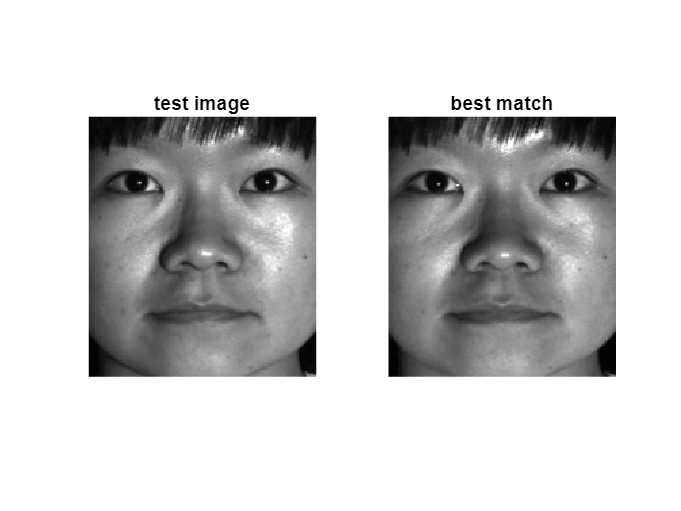

i = 98;
test_image = imread(test_img{1,i});
best_match = imread(train_img{1,best_match_image_index(i)});

figure;
subplot(1,2,1);
imshow(uint8(test_image));
title("test image");

subplot(1,2,2);
imshow(uint8(best_match));
title("best match");
hold off;

### Constructing the Image with the K prominent eigen faces

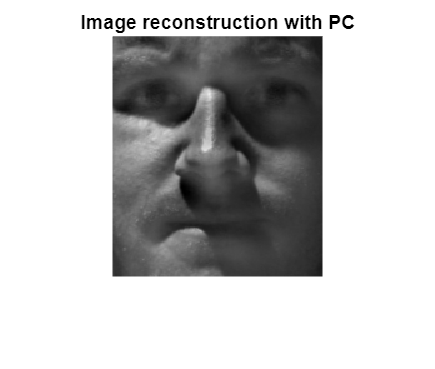

figure;
i = 98;
curent_test_image = imread(train_img{1,i});
current_test_img_proj_coef = train_img_proj_coef(:,i);
reconstructed_flat_image = sum((current_test_img_proj_coef').*(eigen_vectors(:, n_eig_v-k+1:n_eig_v-Leave_top_k)),2);
reconstructed_flat_image_mean_added = reconstructed_flat_image + train_mean_vector;
reconstructed_image = reshape(reconstructed_flat_image_mean_added, [rnum, cnum]);
reconstructed_image = uint8(reconstructed_image);
imshow(reconstructed_image);
title("Image reconstruction with PC");

### Displaying the top 25 eigen vectors

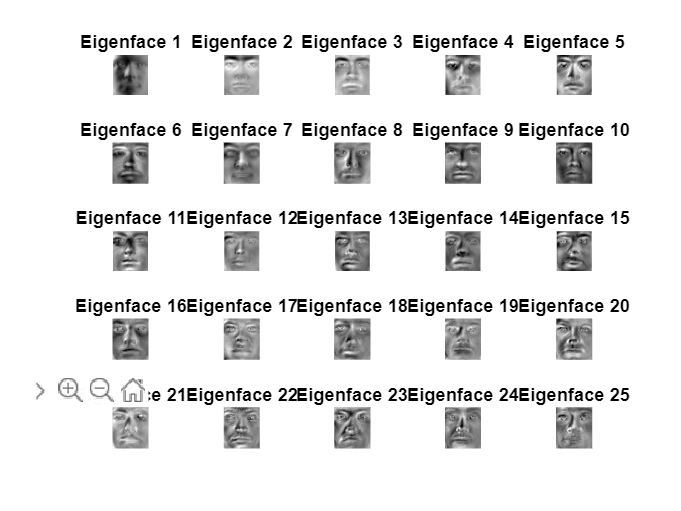

figure;

% Looping to plot the last 25 eigenfaces
for i = 1:25
    % Extractiing the i-th eigenface from the last 25
    eigenface = eigen_vectors(:, n_eig_v-i+1-Leave_top_k);
    
    % Reshaping the eigenface back to the original image dimensions
    reshaped_eigenface = reshape(eigenface, [rnum, cnum]);
    
    % Ploting the eigenface
    subplot(5, 5, i);  % 5x5 grid for 25 eigenfaces
    imshow(reshaped_eigenface, []);
    title(['Eigenface ' num2str(i)]);
end

### Plotting accuracy vs 'k' with  eigenvectors corresponding to 3 largest eigen value

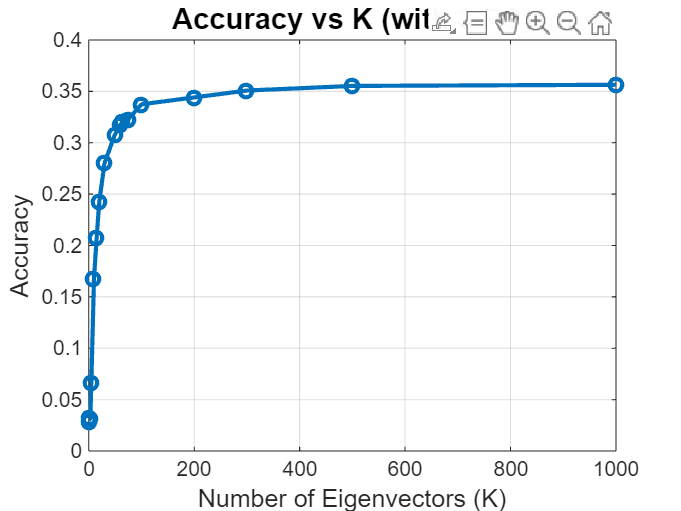

figure;
% plotting number of eigen faces vs accuracy of the model% Data
num_k = [1,2,3,5,10,15,20,30,50,60,65,75,100,200,300,500,1000];
accuracy = [0.0291,0.0324,0.0313, 0.067,0.1676,0.2078,0.2425,0.2804,0.3084, 0.3173, 0.3207,0.3229,0.3374,0.3441,0.3508,0.3553,0.3564];
% Plotting the data
plot(num_k, accuracy, '-o', 'LineWidth', 2, 'MarkerSize', 6);

% Adding title and labels
title('Accuracy vs K (with 3 PC)', 'FontSize', 14);
xlabel('Number of Eigenvectors (K)', 'FontSize', 12);
ylabel('Accuracy', 'FontSize', 12);

% Adding grid for better visibility
grid on;

### Plotting accuracy vs 'k' without  eigenvectors corresponding to 3 largest eigen value

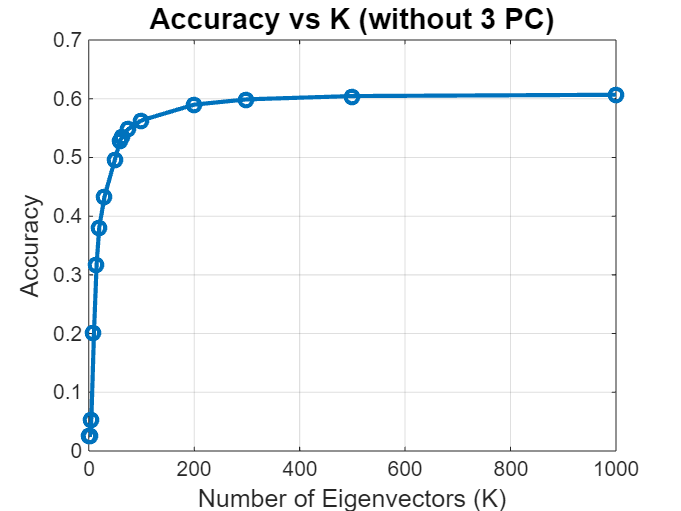

figure;
% plotting number of eigen faces vs accuracy of the model% Data
num_k = [1,2,3,5,10,15,20,30,50,60,65,75,100,200,300,500,1000];
accuracy = [0.0268,0.0268,0.0268,0.0536,0.2022,0.3184,0.3810,0.4335,0.4972,0.5296,0.5363, 0.5486, 0.5631, 0.5899,0.5989, 0.6045,0.6067];

% Plotting the data
plot(num_k, accuracy, '-o', 'LineWidth', 2, 'MarkerSize', 6);

% Adding title and labels
title('Accuracy vs K (without 3 PC)', 'FontSize', 14);
xlabel('Number of Eigenvectors (K)', 'FontSize', 12);
ylabel('Accuracy', 'FontSize', 12);

% Adding grid for better visibility
grid on;